# Data-Driven models perfomance

Desctiption:

    1. Model Identification using ARX model and Hammerstein Wiener model

    2. Neural network model

## Identification system with non-linear Hammerstein Wiener model

Working only for position signal. Other signals are behavior with non-linearities that cann't be good represented using Polynominal-HW-types of models.

Load and prepare data:

clc; clear all; close all; addpath('../utils/'); addpath('../');
set(groot, 'DefaultStairLineWidth', 3)
data = load('models_datastore/data11_1_1.mat');
data_verif = load('models_datastore/data11_1_2.mat');

[f_code,t,i_in_u1_1,i_in_u2_1,i_out_x1,i_out_dx1,i_out_f1]=extract_signals4identification(data);
[f_code,t,i_in_u1_2,i_in_u2_2,i_out_x2,i_out_dx2,i_out_f2]=extract_signals4identification(data_verif);

i_u = i_in_u2_1(:,2) - i_in_u1_1(:,2);
Ts = 1e-3;

### Position Identification

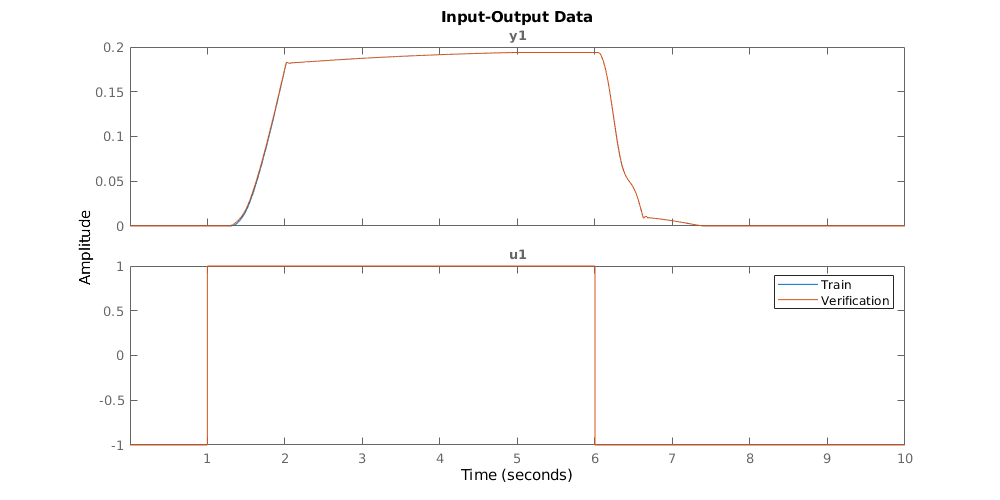

data_x = iddata(i_out_x1(:,2), i_u, Ts);
data_x_verif = iddata(i_out_x2(:,2), i_u, Ts);

figure
plot(data_x, data_x_verif); legend("Train","Verification")

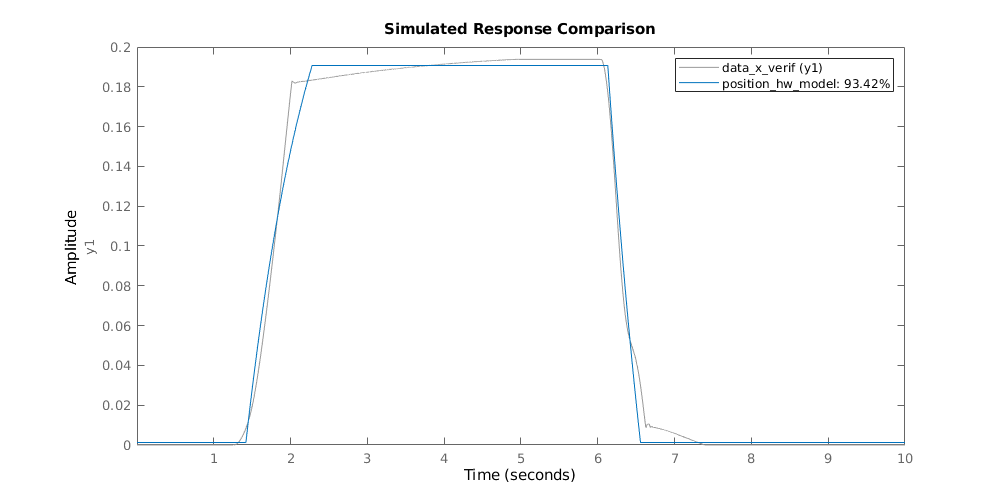

opt = oeOptions('Focus','simulation');
LinearModel = oe(data_x,[3 2 2],opt);
position_hw_model = nlhw(data_x, LinearModel, 'unitgain', 'saturation');
fig = figure;
fig.Position(3:4) = [1000 500];
compare(data_x_verif, position_hw_model)

Result shown general trend of the data but cann't capture non-linear effect from dampers.

### Velocity Identification

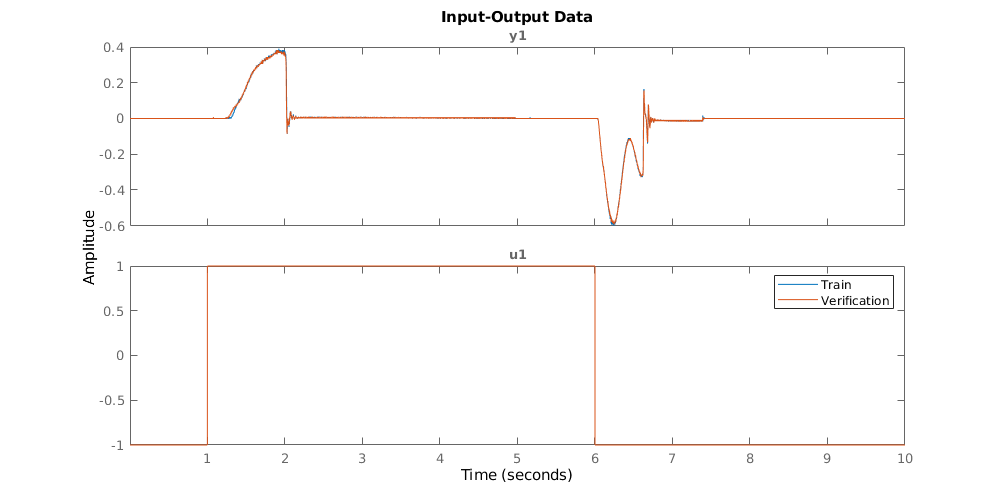

data_dx = iddata(i_out_dx1(:,2), i_u, Ts);
data_dx_verif = iddata(i_out_dx2(:,2), i_u, Ts);
figure
plot(data_dx, data_dx_verif); legend("Train", "Verification")

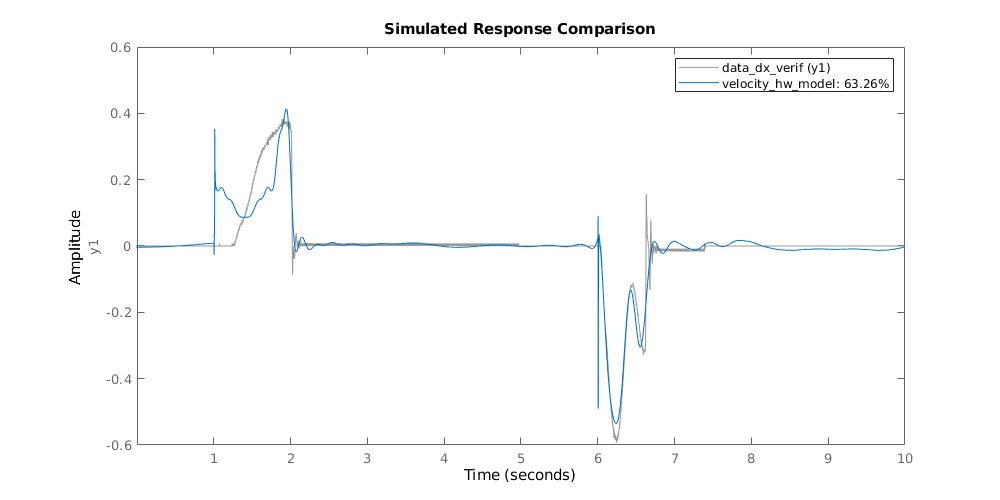

opt = oeOptions('Focus','simulation');
LinearModel = oe(data_dx,[3 4 2],opt);
velocity_hw_model = nlhw(data_dx, LinearModel, 'unitgain', 'wavenet');
fig = figure;
fig.Position(3:4) = [1000 500];
compare(data_dx_verif, velocity_hw_model)

The best result that were achieved is 63%. There is some thend similarities, but result not impressive. The same or worse accuracy were achieved with another signals.

## Neural Network model

Neural network can be used for simulation normal behavior of the system. Example for fitting model on Time-Series data.

Preapare dataset:

clc;clear all;close all;
data1 = load('models_datastore/data11_1_1.mat');
data2 = load('models_datastore/data11_1_2.mat');
data3 = load('models_datastore/data11_1_3.mat');

nn_uuu = load('models_datastore/nnn_uuu.mat').nn_uuu;
nn_xxx = load('models_datastore/nnn_xxx.mat').nn_xxx;

[f_code1,t1,i_in_u1_1,i_in_u1_2,i_out_x1,i_out_dx1,i_out_f1]=extract_signals4identification(data1);
[f_code2,t2,i_in_u2_1,i_in_u2_2,i_out_x2,i_out_dx2,i_out_f2]=extract_signals4identification(data2);
[f_code3,t3,i_in_u3_1,i_in_u3_2,i_out_x3,i_out_dx3,i_out_f3]=extract_signals4identification(data3);

clear data1 data2 data3

nn_u1_1 = nn_refactor(i_in_u1_1);
nn_u2_1 = nn_refactor(i_in_u2_1);
nn_u3_1 = nn_refactor(i_in_u3_1);

nn_u1_2 = nn_refactor(i_in_u1_2);
nn_u2_2 = nn_refactor(i_in_u2_2);
nn_u3_2 = nn_refactor(i_in_u3_2);

nn_x1 = nn_refactor(i_out_x1);
nn_x2 = nn_refactor(i_out_x2);
nn_x3 = nn_refactor(i_out_x3);

nn_dx1 = nn_refactor(i_out_dx1);
nn_dx2 = nn_refactor(i_out_dx2);
nn_dx3 = nn_refactor(i_out_dx3);

nn_f1 = nn_refactor(i_out_f1);
nn_f2 = nn_refactor(i_out_f2);
nn_f3 = nn_refactor(i_out_f3);

nn_u = [nn_u1_1 nn_u2_1 nn_u3_1];
nn_x = [nn_x1 nn_x2 nn_x3];
nn_dx = [nn_dx1 nn_dx2 nn_dx3];
nn_f = [nn_f1 nn_f2 nn_f3];

simo_u = [nn_u1_2; nn_u2_2; nn_u3_2];
simo_T = [nn_x1 preprocess_dx(nn_dx1) nn_f1;
          nn_x2 preprocess_dx(nn_dx2) nn_f2;
          nn_x3 preprocess_dx(nn_dx3) nn_f3;];

siso_u = [nn_u1_2; nn_u2_2; nn_u3_2];
siso_T = [nn_f1; nn_f2; nn_f3];


X = tonndata(nn_uuu.Data,false,false);
T = tonndata(nn_xxx.Data,false,false);


trainFcn = 'trainlm';
inputDelays = 1:3;
feedbackDelays = 1:2;
hiddenLayerSize = 15;
net = narxnet(inputDelays,feedbackDelays,hiddenLayerSize,'open',trainFcn);
[x,xi,ai,t] = preparets(net,X,{},T);

% Setup Division of Data for Training, Validation, Testing
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 20/100;
net.divideParam.testRatio = 10/100;

% Train the Network
[net,tr] = train(net,x,t,xi,ai);
% Test the Network
y = net(x,xi,ai);
e = gsubtract(t,y);
performance = perform(net,t,y)

performance = 6.6011e-10

figure, plotresponse(t,y)
netc = closeloop(net);
netc.name = [net.name ' - Closed Loop'];

[xc,xic,aic,tc] = preparets(netc,X,{},T);
yc = netc(xc,xic,aic);
closedLoopPerformance = perform(net,tc,yc)

closedLoopPerformance = 0.0068

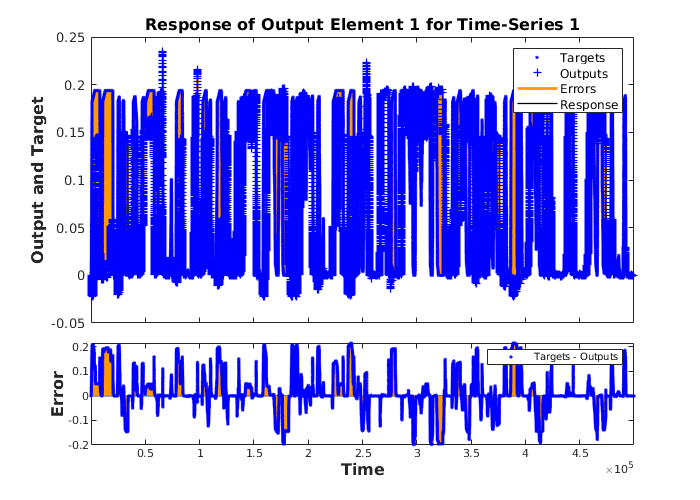

figure, plotresponse(tc,yc)

numTimesteps = size(x,2);
knownOutputTimesteps = 1:(numTimesteps-1e3);
predictOutputTimesteps = (numTimesteps-1e3+1):numTimesteps;
X1 = X(:,knownOutputTimesteps);
T1 = T(:,knownOutputTimesteps);
[x1,xio,aio] = preparets(net,X1,{},T1);
[y1,xfo,afo] = net(x1,xio,aio);
% Next the the network and its final states will be converted to
% closed-loop form to make five predictions with only the five inputs
% provided.
x2 = X(1,predictOutputTimesteps);
[netc,xic,aic] = closeloop(net,xfo,afo);
[y2,xfc,afc] = netc(x2,xic,aic);
multiStepPerformance = perform(net,T(1,predictOutputTimesteps),y2)

multiStepPerformance = 4.1158e-08

nets = removedelay(net);
nets.name = [net.name ' - Predict One Step Ahead'];
[xs,xis,ais,ts] = preparets(nets,X,{},T);
ys = nets(xs,xis,ais);
stepAheadPerformance = perform(nets,ts,ys)

stepAheadPerformance = 6.6011e-10

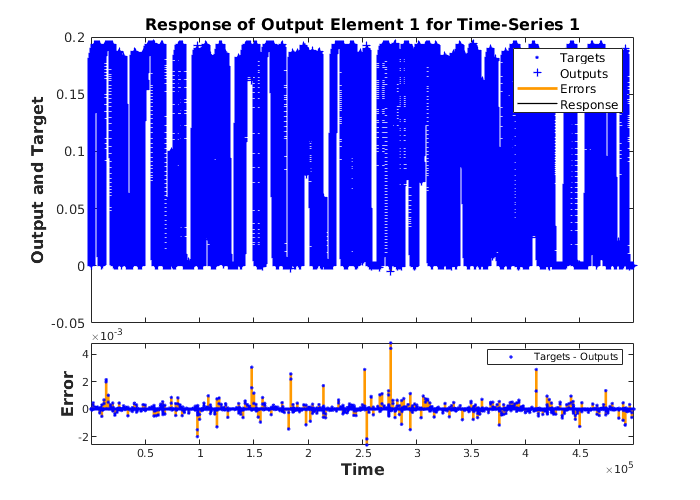

figure, plotresponse(ts,ys)

Functions:

function data = nn_refactor(data)
    data = data(:,2);
end

function y = preprocess_dx(x)
y = lowpass(x,0.2,'Steepness',0.85,'StopbandAttenuation',60);
end

function[] = plot_model_response(X,Y)
Yopen=cell2mat(Yopen);
Yclosed=cell2mat(Yclosed);

t = t(3:end);
T = T(3:end);
T=cell2mat(T);

figure
hold on
plot(t,T(1,:),'b-')
plot(t,Yopen(1,:),'r--')
%plot(t,Yclosed(1,:),'k-.');
hold off
xlabel('Time (sec)');  ylabel('DSP1');
legend('Actual','Predicted (openloop)','Predicted (closedloop)');

figure;
hold on
plot(t,T(2,:),'b-')
plot(t,Yopen(2,:),'r--')
%plot(t,Yclosed(2,:),'k-.');
hold off
xlabel('Time (sec)');  ylabel('DSP1');
legend('Actual','Predicted (openloop)','Predicted (closedloop)');

figure;
hold on
plot(t,T(3,:),'b-')
plot(t,Yopen(3,:),'r--')
%plot(t,Yclosed(3,:),'k-.');
hold off
xlabel('Time (sec)');  ylabel('DSP1');
legend('Actual','Predicted (openloop)','Predicted (closedloop)');

end